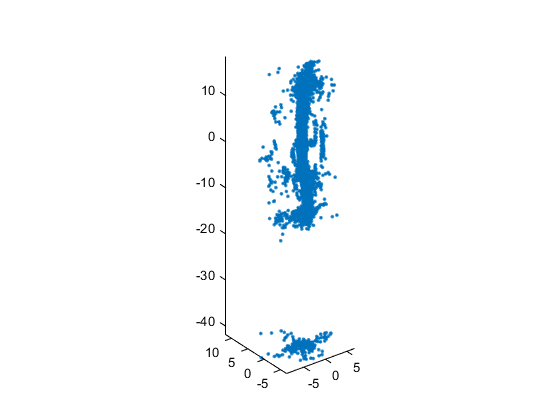

% for jj = 1:2
jj = 2;
data = [xfs.(colors{jj}),yfs.(colors{jj}),zf.(colors{jj})]; % ZF is normalized by Q
plot3(data(:,1),data(:,2),data(:,3),'.')
axis equal

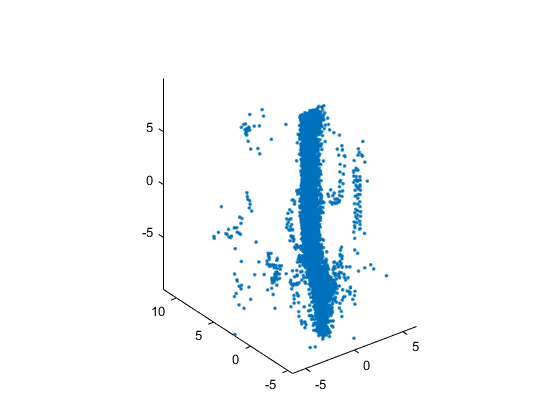

index = abs(data(:,3)) < 10;
exdex = logical(1-index);
data(exdex,:) = [];
plot3(data(:,1),data(:,2),data(:,3),'.')
axis equal

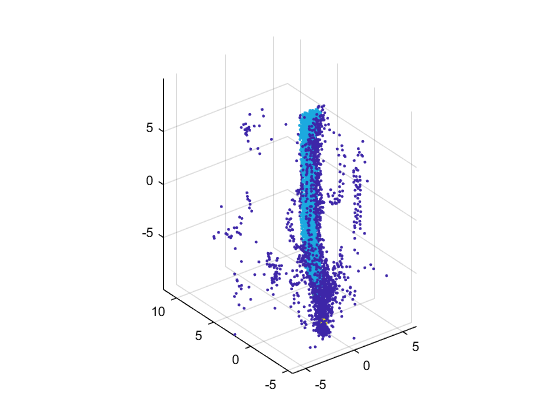

% Here we use a db scan to determine the 'central column'
clust = dbscan(data, 0.3, 15);
scatter3(data(:,1),data(:,2),data(:,3),5,clust,'filled')
axis equal

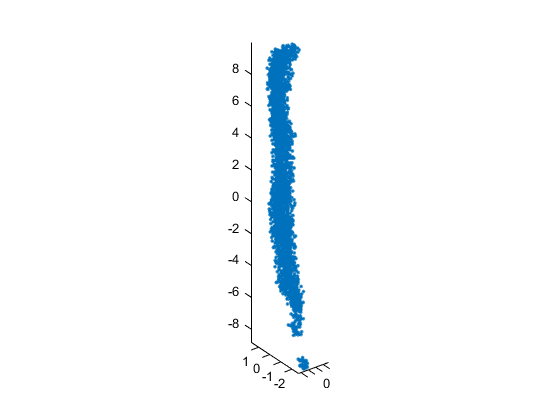

model_data = data(clust~=-1,:);
plot3(model_data(:,1),model_data(:,2),model_data(:,3),'.')
axis equal

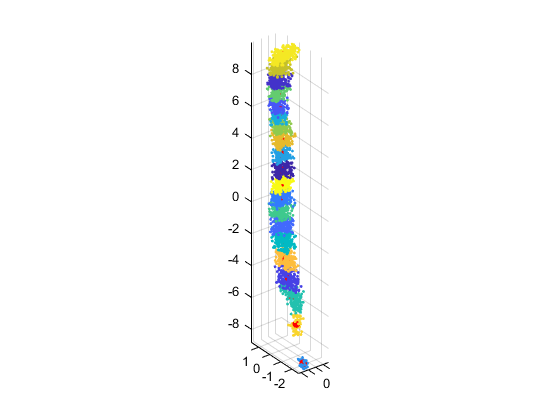

k = 20;
idx = kmeans(model_data(:,3),k);
scatter3(model_data(:,1),model_data(:,2),model_data(:,3),5,idx,'filled')
axis equal
for  i = 1:k
    ind = idx == i;
    avg_points(i,:) = mean(model_data(ind,:));
end
hold on
plot3(avg_points(:,1),avg_points(:,2),avg_points(:,3),'.r','MarkerSize',20)
hold off
cal.(colors{jj}).x_tilt = avg_points(:,1);
cal.(colors{jj}).y_tilt = avg_points(:,2);
cal.(colors{jj}).z_tilt = avg_points(:,3);
[splx, sply] = get_axial_tilt_spline(cal.(colors{jj}),zf.(colors{jj}));

%     plot3(xfs.(colors{jj})-splx,yfs.(colors{jj})-sply,zf.(colors{jj}),'.')
index = zf_um.(colors{jj}) ~= -5;
xt = xf.(colors{jj})(index);
yt = yf.(colors{jj})(index);
zt = zf_um.(colors{jj})(index)/q;
hold off

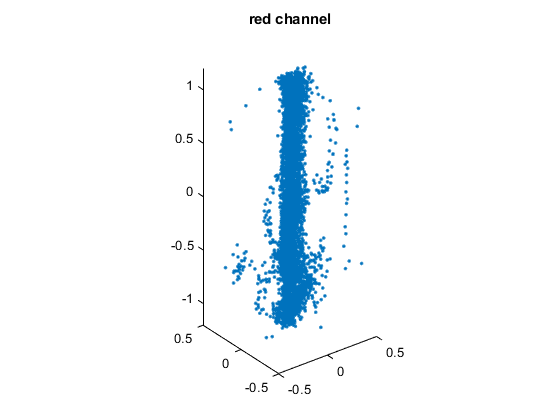

ncoords = make_astigmatism_corrections([xt,yt,zt],cal.(colors{jj}),q);
plot3(ncoords(:,1),ncoords(:,2),ncoords(:,3),'.')
hold on
% plot3(data(:,1)*q,q*data(:,2),q*data(:,3),'.')
hold off
axis equal
xlim([-0.5 0.5])
ylim([-0.5 0.5])
zlim([-10 10]*q)
title([colors{jj},' channel'])


% The model will be based off of the
selection_cluster = clust == mode(clust(clust ~= -1));
model = data(selection_cluster,:);
[dz, I] = sort(model(:,3));
model = model(I,:);
%     plot3(model(:,1),model(:,2),model(:,3),'.')
splz = min(model(:,3)):0.1:max(model(:,3));
for i = 1:numel(splz)
    ind = abs(model(:,3) - splz(i)) < 0.1;
    average_points(i,:) = mean(model(ind,:),1);
    
end
for i = 1:3
    average_points(:,i) = gausssmooth(average_points(:,i),8,20);
end
% Assign axial tilt parameters to z_calibration
cal.(colors{jj}).x_tilt = average_points(:,1);
cal.(colors{jj}).y_tilt = average_points(:,2);
cal.(colors{jj}).z_tilt = average_points(:,3);
figure
if make_graphs == 0
    figure
    scatter3(xfs.(colors{jj}),yfs.(colors{jj}),zf.(colors{jj}),5,clust == mode(clust))
    zlim([-10 10])
    
    plot3(average_points(:,1),average_points(:,2),average_points(:,3),'.')
    figure
    plot3(xfs.(colors{jj}),yfs.(colors{jj}),zf.(colors{jj}),'.')
    hold on
end
[splx, sply] = get_axial_tilt_spline(cal.(colors{jj}),zf.(colors{jj}));


%     plot3(xfs.(colors{jj})-splx,yfs.(colors{jj})-sply,zf.(colors{jj}),'.')
index = zf_um.(colors{jj}) ~= -5;
xt = xf.(colors{jj})(index);
yt = yf.(colors{jj})(index);
zt = zf_um.(colors{jj})(index)/q;
hold off
ncoords = make_astigmatism_corrections([xt,yt,zt],cal.(colors{jj}),q);

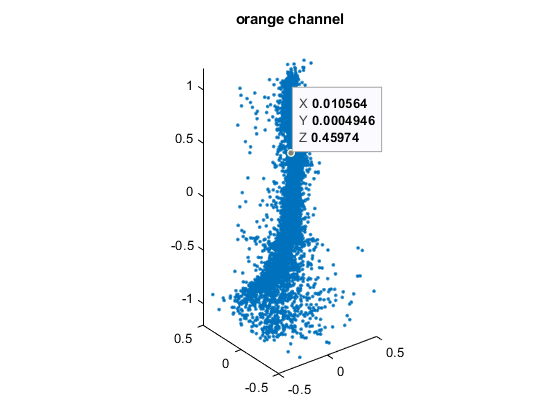

plot3(ncoords(:,1),ncoords(:,2),ncoords(:,3),'.')
axis equal
xlim([-0.5 0.5])
ylim([-0.5 0.5])
zlim([-10 10]*q)
title([colors{jj},' channel'])


% end

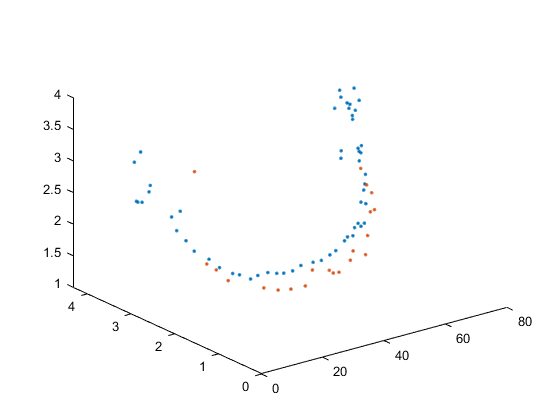

% Z xcor result
% sig1 = sigr;
% sig2 = sigc;
% f1 = sig1(:,1);
% f2 = sig2(:,1);
% n = numel(f1);
% sx1 = sig1(:,2);
% sy1 = sig1(:,3);
% sx2 = sig2(:,2);
% sy2 = sig2(:,3);
% frame1 = sig1(:,1);
% frame2 = sig2(:,1);
% plot3(f1,sx1,sy1,'.')
% hold on
% plot3(f2,sx2,sy2,'.')
% hold off

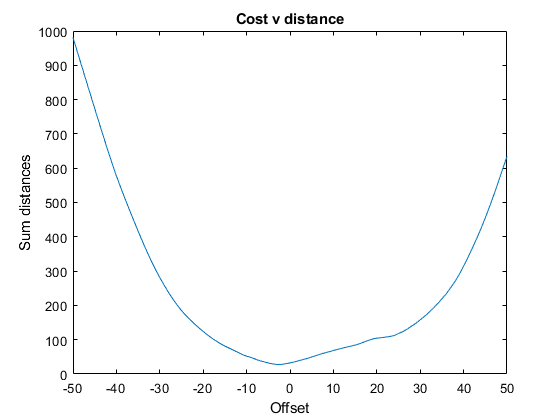

% % Using a Nearest Neighbor approach to scan overlap
% k = 2;
% offsets = -50:50; % 100 nm scan
% for i = 1:numel(offsets)
%     sigd = sigc;
%     sigd(:,1) = sigd(:,1) + offsets(i);
%     [I, distance] = knnsearch(sigr,sigd,'k',k);
%     cost(i) = sum(distance(:));
% end
% plot(offsets,cost)
% xlabel('Offset')
% ylabel('Sum distances')
% title('Cost v distance')

% [M,I] = min(cost);
% disp(['Minimum cost comes at ', num2str(offsets(I)), 'nm offset'])

Minimum cost comes at -3nm offset


% plot3(f1,sx1,sy1,'.')
% hold on
% plot3(f2,sx2,sy2,'.')
% for i = 1:numel(I)
%     plot3([f2(i), f1(I(i))],[sx2(i),sx1(I(i))],[sy2(i),sy1(I(i))],'k')
% end
% hold off

% Selection criteria for xcor scan
% jj = 1;
% indy = sx.(colors{jj}) < 5 & sx.(colors{jj}) >0 & sy.(colors{jj}) < 5 & sy.(colors{jj}) > 0;
% % Tolerance for pixel uncertainty
% indy = indy & sxc.(colors{jj}).^0.5*q < 5 & syc.(colors{jj}).^0.5*q < 5 ;
% count = 0;
% while true
%     refp = mode(psf.(colors{jj})(indy)); % find psf scan w/ the most number of passed fits, this is our reference psf
%     rid = round(psf.(colors{jj})) == round(refp); % build an index for the reference ID
%     sigr = [fnum.(colors{jj})(rid),sx.(colors{jj})(rid),sy.(colors{jj})(rid)]; % build reference sigma scan
%     sxs = gausssmooth(sigr(:,2),5,10);
%     if var(sigr(:,2)-sxs) < 0.1
%         break;
%     else
%         indy = indy & psf.(colors{jj}) ~= round(refp);
%         count = count +1;
%     end
% end
% refp

refp = 130

% disp(['We had to skip ', num2str(count), ' scans to get the one shown'])

We had to skip 2 scans to get the one shown


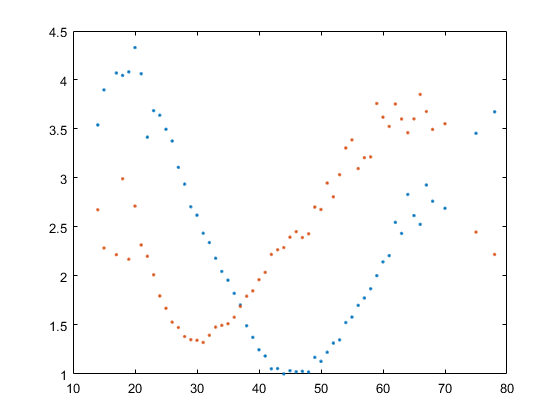

% plot(sigr(:,1),sigr(:,2),'.')
% hold on
% plot(sigr(:,1),sigr(:,3),'.')
% hold off